# 2.6 - Sessão 2 – Oscilador de Onda Rectangular e Secção Biquadrática de Rauch

## 2.1 Objectivos

clear;

## 2.2 Equipamento para Ensaio Laboratorial

R1 = 820;   %(Ohm)
R2 = 3.9e3; %(Ohm)
R3 = 150;   %(Ohm)
R4 = 1.5e3; %(Ohm)
R5 = 1.5e3; %(Ohm)
R6 = 47e3;  %(Ohm)
R8 = 1.2e3; %(Ohm)
R9 = 1.2e3; %(Ohm)
P1 = 100e3; %(Ohm)

C1 = 180e-9; %(F)
C2 = 100e-9; %(F)
C3 = 27e-9;  %(F)
C4 = 27e-9;  %(F)
C5 = 10e-9;  %(F)

Vcc = 12; %(V)

OpAmp = 741;
Timer = 555;

Diode = 333;
U_gamma = 1.4; %(V)

## 2.6 **Filtro Passa-Banda de Rauch **

f0 = 1e3; %(Hz)
w0 = 2*pi*f0 %(rad/s)

w0 = 6.2832e+03

B = 2*pi*250; %(Hz)
Gf0dB = 24; %(dB)

% Butterworth parameters
epsl = 1;
K = 10^(Gf0dB/20)f0 = ;
s = tf('s');
s_ = epsl*(s^2+w0^2)/(B*s);
T = K/(s_+1);

T


T =
 
         2.49e04 s
  -----------------------
  s^2 + 1571 s + 3.948e07
 
Continuous-time transfer function.



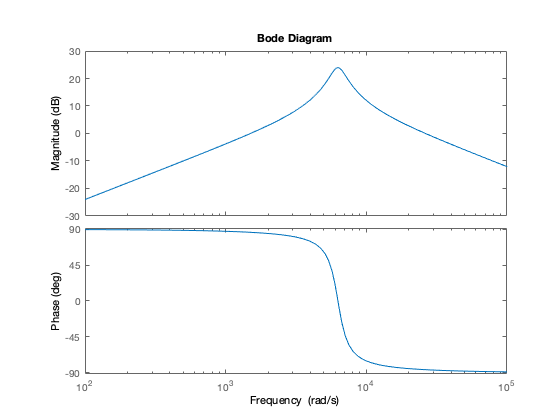

bode(T)

frsp = evalfr(T,f) 

% figure('units','normalized','outerposition',[0 0 1 1]);
% hold on;
% set(gca,'FontSize',35);
% ax = gca;
% ax.XGrid = 'on';
% ax.YGrid = 'on';
% %title('Distance from critical point (example)');
% p = plot(t,VM);
% p.LineWidth = 3;
% p = plot(t,VC1);
% p.LineWidth = 3;
% ylabel('$p_y$','Interpreter','latex');
% xlabel('$p_x$','Interpreter','latex');
% legend('V_M','V_{C_1}');
% hold off